# Coin exchange model for relaxation process

## コイン交換モデル：概要

ここでは2つの系A，Bが熱エネルギーの交換によって平衡状態に緩和する過程を，コイン交換モデルで表現する．

このモデルではAとBの2人がコインを交換することを考える．

はじめAは青いコインを $N$ 枚，Bは赤いコインを $N$ 枚持っているものとし，青と赤のコインにはそれぞれ，エネルギーに見立てた得点 $+1,-1$ が割り当てられているものとする．

その後，Aの持っているコインとBの持っているコインを1枚ずつ無作為に選んで交換するという操作を繰り返す．

数値シミュレーションの結果から読み取れるように，ある程度時間が経つと (試行を繰り返すと)， A (またはB) の持つ赤と青のコインはほぼ同数となる．

すなわちA，B各々の合計得点 $E_{\mathrm{A}},E_{\mathrm{B}}$ (を規格化した値 $\eta_{\mathrm{A}}
=E_{\mathrm{A}}/N,
\eta_{\mathrm{B}}
=E_{\mathrm{B}}/N$) はゼロに緩和する．

しかしながら $\eta_{\mathrm{A}},
\eta_{\mathrm{B}}$ が平均値ゼロの周りにゆらいでいる様子も見て取れる．

($N$を大きくすると，このゆらぎは目立たなくなる．)

ここから緩和過程を平均挙動とゆらぎに分離して理解することが動機付けられる．

clear all; clf;

## $\eta_{\mathrm{A}},
\eta_{\mathrm{B}}$$\eta_{\mathrm{A}},
\eta_{\mathrm{B}}$時系列のみの表示

$\eta_{\mathrm{A}},
\eta_{\mathrm{B}}$ の時系列

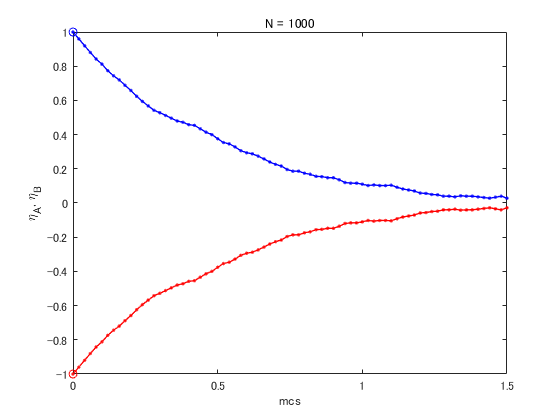

%時系列のみ表示する
%
T = 1.5; %試行回数（モンテカルロステップ）
N = 1000; %コイン数
step = 0.02;

s01 =  N;
s02 = -N;

x1 = 1:N;

tm  = [0/N];
sm1 = [s01/N];
sm2 = [s02/N];

subplot(1, 1, 1);

plot(tm, sm1, '-ob')
hold on
plot(tm, sm2, '-or') 
title(['N = ', num2str(N)])

for j = step:step:T
    for k = 1:N*step
        if rand < (s01/N + 1)*0.5 
            ch1 = 1;
        else
            ch1 = -1;
        end
        if rand < (s02/N + 1)*0.5 
            ch2 = 1;
        else
            ch2 = -1;
        end
        s01 = s01 - ch1 + ch2;
        s02 = s02 + ch1 - ch2;
    end

    tm  = [tm  j];
    sm1 = [sm1 s01/N];
    sm2 = [sm2 s02/N];
    plot(tm, sm1, '.-b', "LineWidth", 1)
    plot(tm, sm2, '.-r', "LineWidth", 1)
    xlabel('mcs')
    ylabel('\eta_A, \eta_B')
    drawnow
end
hold off

### 指数関数によるフィッティング

%% 近似: '新規近似 1'。
[xData, yData] = prepareCurveData( tm, sm1 );

% 近似タイプとオプションを設定します。
ft = fittype( 'exp1' );
excludedPoints = excludedata( xData, yData, 'Indices', [39 40 41 42 43 44 45 46 47 48 49 50 51 52 53 54 55 56 57 58 59 60 61 62 63 64 65 66 67 68 69 70 71 72 73 74 75 76] );
opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
opts.Display = 'Off';
opts.StartPoint = [0.990369374969461 -1.96186109596074];
opts.Exclude = excludedPoints;

% モデルをデータに近似します。
[fitresult, gof] = fit( xData, yData, ft, opts )

fitresult =      一般モデル Exp1:
     fitresult(x) = a*exp(b*x)
     係数 (95% の信頼限界):
       a =      0.9917  (0.98, 1.003)
       b =      -2.014  (-2.058, -1.971)

gof = フィールドをもつ struct :
           sse: 0.0065
       rsquare: 0.9966
           dfe: 36
    adjrsquare: 0.9965
          rmse: 0.0134


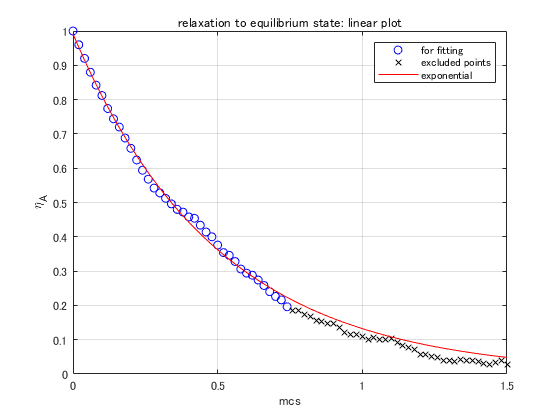


% データの近似をプロットします。
figure( 'Name', '新規近似 1' );
h = plot( fitresult, xData, yData, 'bo', excludedPoints, 'kx' );
legend( h, 'for fitting', 'excluded points', 'exponential', 'Location', 'NorthEast', 'Interpreter', 'none' );
% ラベル Axes
xlabel( 'mcs' );
ylabel( '\eta_A');
title('relaxation to equilibrium state: linear plot')
grid on

### 片対数グラフでの表示

平衡状態への緩和過程では，合計得点 $E_{\mathrm{A}}$ は時間とともに指数関数的に緩和することが理論的に知られている．

そこで $\eta_{\mathrm{A}}$ の時系列を片対数グラフとして表示すると，初期の緩和過程におけるデータは直線状となっていることが見て取れる．

これは確かに $\eta_{\mathrm{A}}$ が指数緩和していることを意味する．

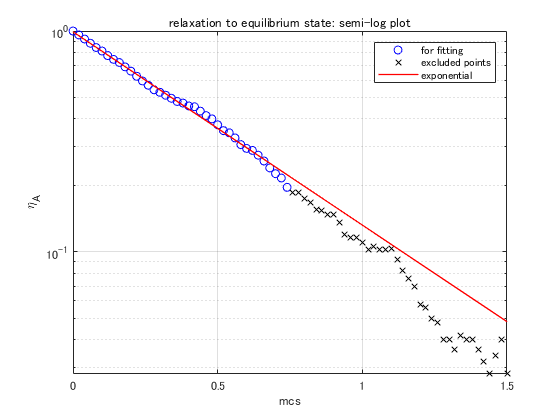

semilogy(xData(excludedPoints==0), yData(excludedPoints==0), 'bo', DisplayName='for fitting' );
hold on
semilogy(xData(excludedPoints==1), yData(excludedPoints==1), 'kx', DisplayName='excluded points' );
semilogy(xData, fitresult(xData), 'r-', LineWidth=1, DisplayName='exponential');
hold off
xlabel( 'mcs' );
ylabel( '\eta_A');
title('relaxation to equilibrium state: semi-log plot')
legend()
grid on

## 付録

### Animation for coin exchange

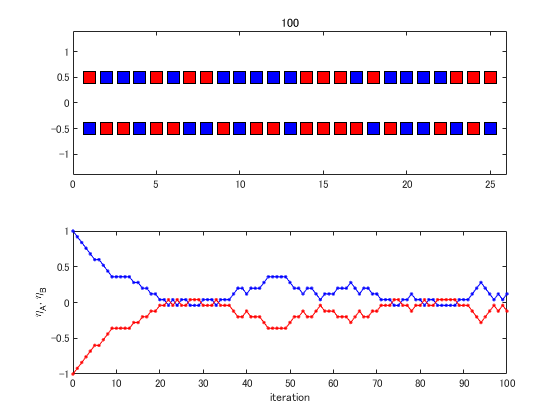

%random walk 
T = 100; %試行回数
N = 25; %コイン数

s1 =  ones(2, N);
s1(2,:) = -s1(2,:);

x1 = 1:N;
ms = fix(300/N);

%subplot(m,n,p)

subplot(2, 1, 1);
plot(x1, 0.5 * s1(1,:), 'ks', "MarkerSize", ms, "MarkerFaceColor",'b')
hold on 
plot(x1, 0.5 * s1(2,:), 'ks', "MarkerSize", ms, "MarkerFaceColor",'r')
xlim([-0 N+1])
ylim([-1.4 1.4])
title(0);

tm  = [0];
sm1 = [sum(s1(1, :))/N];
sm2 = [sum(s1(2, :))/N];

for j = 1:T
    r1 = fix(rand * N) + 1;
    r2 = fix(rand * N) + 1;
    t1 = s1(1, r1);
    %t2 = s1(2, r2);
    s1(1, r1) = s1(2, r2);
    s1(2, r2) = t1;
    
    subplot(2, 1, 1);
    plot([r1 r2], 0.5*[1 -1], 'k-') 
    pause(0.1)
    plot([r1 r2], 0.5*[1 -1], 'w-') 
    for k = 1:N
        if s1(1, k) > 0
            plot([k], 0.5, 'ks', "MarkerSize", ms, "MarkerFaceColor",'b')
        else
            plot([k], 0.5, 'ks', "MarkerSize", ms, "MarkerFaceColor",'r')
        end
        
        if s1(2, k) > 0
            plot([k], -0.5, 'ks', "MarkerSize", ms, "MarkerFaceColor",'b')
        else
            plot([k], -0.5, 'ks', "MarkerSize", ms, "MarkerFaceColor",'r')
        end
    end
    %pause(1);
    title(j);
    
    subplot(2, 1, 2);
    tm  = [tm  j];
    sm1 = [sm1 sum(s1(1, :))/N];
    sm2 = [sm2 sum(s1(2, :))/N];
    plot(tm, sm1, '.-b')
    hold on
        plot(tm, sm2, '.-r')
    hold off
    xlabel('iteration')
    ylabel('\eta_A, \eta_B')

    drawnow
end
hold off